% 功能:产生塔康地面站信号
% 作者：TW
% 日期：2025.9.21
% 版本：1.0


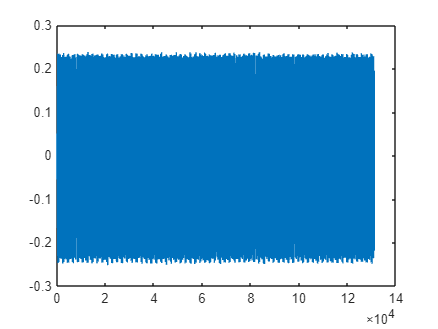

clc;
clear;
data=readmatrix("111.csv");
plot(data);

%
fs=100e9;
fc=338.201e6;
sps=fs/1e6;
spectrumScope = spectrumAnalyzer("SampleRate",fs, ...
                "ViewType","spectrum", ...
                "SpectrumType","power", ...
                "PlotAsTwoSidedSpectrum",true, ...
                "Method","welch", ...
                "AveragingMethod","vbw", ...
                "SpectrumUnits", "dBm", ...
                "AxesScaling", "Manual", ...
                "YLimits", [-80 +0], ...
                "ForgettingFactor", 0.95, ...
                "FrequencyOffset", 0);

% spectrumScope(data.');
t=0:1/fs:(length(data)-1)/fs;
% rxWaveform=data.*exp(-1i*2*pi*fc*t+pi*1/4);
% spectrumScope(data.');
% spectrumScope(rxWaveform.');
a=1;
rolloff=0.35;
rcrFilt = comm.RaisedCosineReceiveFilter(...
    'Shape', 'Square root', ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', 4, ...
    'InputSamplesPerSymbol', a*sps, ...
    'DecimationFactor', a);
carrier_cos = cos(2*pi*fc*t);
carrier_sin = sin(2*pi*fc*t);

% 正交解调：乘以正交载波
% rx_signal=rx_signal(300:end-300);
rx_signal =data;
I_demod = 2 * rx_signal .* carrier_cos(1:length(rx_signal));
Q_demod = -2 * rx_signal .* carrier_sin(1:length(rx_signal));

% 低通滤波去除高频分量
lpFilt = designfilt('lowpassfir', 'FilterOrder', 50, ...
    'CutoffFrequency', 1e6, 'SampleRate', fs);

I_baseband = filtfilt(lpFilt, I_demod);
Q_baseband = filtfilt(lpFilt, Q_demod);

% I_baseband = I_demod;
% Q_baseband =  Q_demod;
% 组合为复基带信号
rx_baseband = I_baseband + 1j * Q_baseband;

fprintf('正交解调完成\n');

正交解调完成



%% 6. 匹配滤波
fprintf('\n6. 匹配滤波...\n');


6. 匹配滤波...


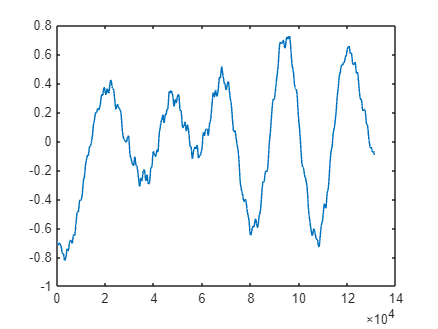

rcrFilt = comm.RaisedCosineReceiveFilter(...
    'Shape', 'Square root', ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', 6, ...
    'InputSamplesPerSymbol', sps, ...
    'DecimationFactor', 1);
% % 使用相同的根升余弦滤波器进行匹配滤波
filterSpan = 4;  % 滤波器跨度
rrcFilter = rcosdesign(rolloff, filterSpan, sps, 'sqrt');
rx_filtered = conv(rx_baseband, rrcFilter, 'same');
% rx_filtered = rcrFilt(rx_baseband);
symbolSync = comm.SymbolSynchronizer;
% rx_filtered= symbolSync (rx_filtered);       
% rx_filtered = rx_filtered(groupDelay+1:end);

plot(real(rx_filtered));

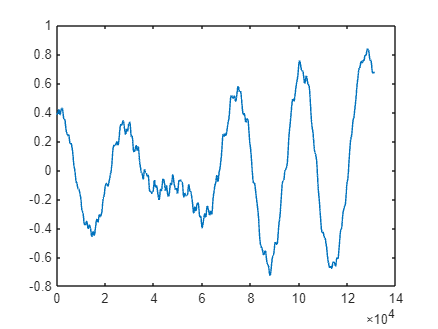

plot(imag(rx_filtered));

% 下采样到符号率
start=400;
rx_filtered=rx_filtered./max(abs(rx_filtered));
rx_symbols = rx_filtered(start:sps:end).*exp(-j*pi*3/5);

cd = comm.ConstellationDiagram(ShowReferenceConstellation=true, ...
    EnableMeasurements=true,...
    MeasurementInterval='Current display',...
    EVMNormalization='Average constellation power');

cd(rx_symbols.');